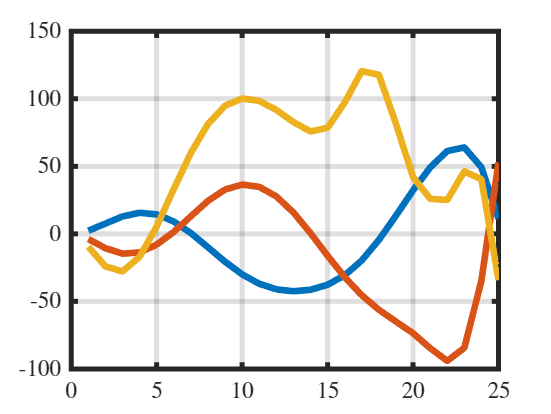

clear; close all;
rng(2);

% Number references
W = 3;
% Number samples
N = 25;
% Reference cell
rc = cell(W,1);
% Inital inputs
uc = cell(W,1);
% Iterate
for w = 1:W
    % Random input
    u = 1.1* randn(N, 1);
    % Butterworth-Filter
    [b,a] = butter(4, 0.1);
    % Filter
    u = filtfilt(b, a, u);
    % Apply to dynamics
    r = run_double_pendulum_feedforward_dynamics(u);
    rc{w,1} = r;
    % Plot
    plot(rad2deg(r)); hold on;
    % Inital input
    uc{w,1} = 0.05*randn(N,1);
end